## Setup

clear;
close all;

## Question 3

V_m = 18;             % [V]
omega_noload = 11800; % [rpm]
R = 0.68;             % [ohms]
L = 0.078;            % [mH]
J = 9.82;             % [g*cm^2]
b = 3.14*10^-4;       % [mN*m*sec]
R_wh = 4.57;          % [K/W]
R_ha = 13.6;          % [K/W]
tou_w = 22;           % [sec]
tou_h = 646;          % [sec]
T_max = 125;          % [deg C]
T_amb = 25;           % [deg C]

### Part a)

K_m = omega_noload/V_m % [rpm/V]

K_m = 655.5556

### Part b)

K_m = K_m * 2*pi()/60 % [rpm/V] -> [rad/V*sec]

K_m = 68.6496

b = b * 10^-3 % [mN*m*sec] -> [N*m*sec]

b = 3.1400e-07


syms K_t K_v

eqn1 = K_m == K_t/(b*R + K_t*K_v)

$$eqn1 = \frac{590\,\pi }{27}=\frac{K_{t}}{K_{t}\,K_{v}+\frac{8066557531378615}{37778931862957161709568}}$$

eqn2 = K_t == K_v

$$eqn2 = K_{t}=K_{v}$$

[K_t, K_v] = solve([eqn1 eqn2], [K_t K_v])

$$K\_t = \left(\begin{array}{c} -\frac{590\,\sqrt{\frac{729}{348100}-\frac{8066557531378615\,\pi^{2}}{9444732965739290427392}}-27}{1180\,\pi }\\ \frac{590\,\sqrt{\frac{729}{348100}-\frac{8066557531378615\,\pi^{2}}{9444732965739290427392}}+27}{1180\,\pi } \end{array}\right)$$

$$K\_v = \left(\begin{array}{c} -\frac{590\,\sqrt{\frac{729}{348100}-\frac{8066557531378615\,\pi^{2}}{9444732965739290427392}}-27}{1180\,\pi }\\ \frac{590\,\sqrt{\frac{729}{348100}-\frac{8066557531378615\,\pi^{2}}{9444732965739290427392}}+27}{1180\,\pi } \end{array}\right)$$

double(min(K_t)) % [N*m/A] = [V*sec/rad] too small so ignore

ans = 1.4673e-05

K_t = double(max(K_t)) % [N*m/A] = [V*sec/rad]

K_t = 0.0146

K_v = double(max(K_v)) % [V*sec/rad] = [N*m/A]

K_v = 0.0146

### Part c)

i_stall = V_m/R % [A]

i_stall = 26.4706

### Part d)

T_stall = K_t*i_stall % [N*m]

T_stall = 0.3852

T_stall = T_stall * 10^3 % [N*m] -> [mN*m]

T_stall = 385.2013

### Part e)

b % [N*m*sec]

b = 3.1400e-07

speed_torque_gradient = R/(b*R+K_t*K_v) % [rad/N*m*sec]

speed_torque_gradient = 3.2079e+03

### Part f)

b % [N*m*sec]

b = 3.1400e-07

omega_noload = omega_noload * 2*pi()/60 % [rpm] -> [rad/sec]

omega_noload = 1.2357e+03

i_noload = (b/K_t)*omega_noload % [A]

i_noload = 0.0267

### Part g)

T_stall = T_stall * 10^-3  % [mN*m] -> [N*m]

T_stall = 0.3852

T_max_power = 0.5*T_stall % [N*m]

T_max_power = 0.1926

omega_max_power = 0.5*omega_noload % [rad/sec]

omega_max_power = 617.8466

P_max = T_max_power*omega_max_power % [W]

P_max = 118.9977

### Part h)

i_nom = sqrt((T_max-T_amb)/(R*(R_wh+R_ha))) % [A]

i_nom = 2.8449

K_m % [rad/V*sec]

K_m = 68.6496

b % [N*m*sec]

b = 3.1400e-07

T_nom = (1/(K_m))*i_nom - (b/K_t)*V_m % [N*m]

T_nom = 0.0411

T_nom = T_nom * 10^3 % [N*m] -> [mN*m]

T_nom = 41.0526

### Part i)

T_nom = T_nom * 10^-3  % [mN*m] -> [N*m]

T_nom = 0.0411

T_stall % [N*m]

T_stall = 0.3852

speed_torque_gradient % [rad/N*m*sec]

speed_torque_gradient = 3.2079e+03

omega_nom = speed_torque_gradient*(T_stall - T_nom) % [rad/sec]

omega_nom = 1.1040e+03

P_nom = T_nom*omega_nom % [W]

P_nom = 45.3220

### Part j)

C_w = tou_w/R_wh % [J/K]

C_w = 4.8140

C_h = tou_h/R_ha % [J/K]

C_h = 47.5000

## Question 4

### Part a)

T_stall % [Nm]

T_stall = 0.3852

% number of torques
num_T_load = 1000;
T_load = linspace(0, T_stall, num_T_load) % [Nm]

T_load =          0    0.0004    0.0008    0.0012    0.0015    0.0019    0.0023    0.0027    0.0031    0.0035    0.0039    0.0042    0.0046    0.0050    0.0054    0.0058    0.0062    0.0066    0.0069    0.0073    0.0077    0.0081    0.0085    0.0089    0.0093    0.0096    0.0100    0.0104    0.0108    0.0112    0.0116    0.0120    0.0123    0.0127    0.0131    0.0135    0.0139    0.0143    0.0147    0.0150    0.0154    0.0158    0.0162    0.0166    0.0170    0.0174    0.0177    0.0181    0.0185    0.0189


T_load = transpose(T_load) % [Nm]

T_load =          0
    0.0004
    0.0008
    0.0012
    0.0015
    0.0019
    0.0023
    0.0027
    0.0031
    0.0035


### Part b)

T_stall % [N*m]

T_stall = 0.3852

speed_torque_gradient % [rad/N*m*sec]

speed_torque_gradient = 3.2079e+03

omega_ss = speed_torque_gradient*(T_stall - T_load) % [rad/sec]

omega_ss = 1.0e+03 *

    1.2357
    1.2345
    1.2332
    1.2320
    1.2307
    1.2295
    1.2283
    1.2270
    1.2258
    1.2246


### Part c)

P_mech = T_load.*omega_ss % [W]

P_mech =          0
    0.4760
    0.9510
    1.4251
    1.8982
    2.3704
    2.8416
    3.3119
    3.7812
    4.2496


### Part d)

b % [N*m*sec]

b = 3.1400e-07

K_t % [V*sec/rad]

K_t = 0.0146

P_elec = V_m*((T_load + b*omega_ss)/K_t) % [W]

P_elec =     0.4799
    0.9564
    1.4329
    1.9093
    2.3858
    2.8623
    3.3387
    3.8152
    4.2917
    4.7681


efficiency = P_mech./P_elec % [-]

efficiency =          0
    0.4977
    0.6637
    0.7464
    0.7956
    0.8282
    0.8511
    0.8681
    0.8811
    0.8912


## Question 5

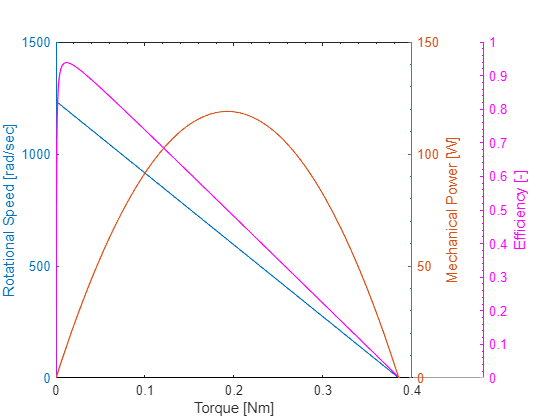

figure('Position', [0 0 1000 600]);
[ax, hlines] = plotyyy(T_load, omega_ss, T_load, P_mech, T_load, efficiency, ["Rotational Speed [rad/sec]", "Mechanical Power [W]", "Efficiency [-]"]);
set(hlines,LineWidth=1)
set(get(ax(1),'xlabel'),'String',"Torque [Nm]");